# **Lab 06 SNS**

## **Syed Muhammad Asad Ali**

### **sa09475**

#### **Task 1**

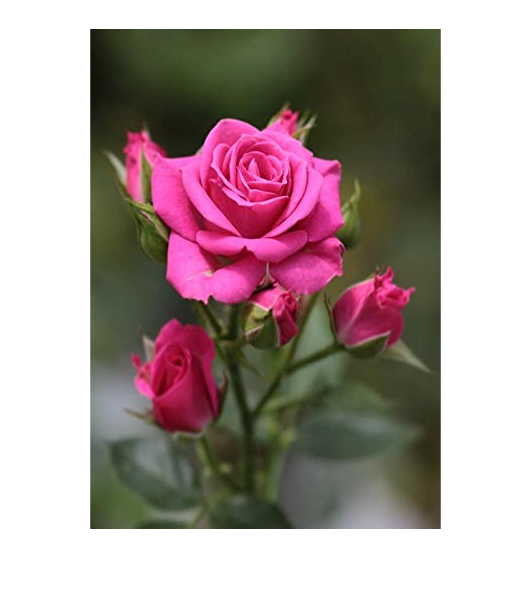

%Read image, visualize it, and display its size and class.
I = imread('flower.jpg');
% Convert to double precision
I = im2double(I);
% Display
figure,
imshow(I)

whos I

  Name        Size                 Bytes  Class     Attributes

  I         500x351x3            4212000  double              



% Split the image into the 3 component color intensity planes or matrices.
[R, G, B] = imsplit(I);
whos R

  Name        Size               Bytes  Class     Attributes

  R         500x351            1404000  double              



% Create a 2-D convolution filter or kernel for averaging or smoothing
W = 23;
h = ones(W)./W.^2

h =     0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019  

%Convolve R with h to blur the image
Ravg = conv2(R,h,"same");
% Convolve G with h to blur the image
Gavg =  conv2(G,h,"same");%Write your code here
% Convolve B with h to blur the image
Bavg = conv2(B,h,"same");%Write your code here
% Concatenate the three matrices to put together the color image
Iavg = cat(3,Ravg,Gavg,Bavg);
whos Iavg

  Name        Size                 Bytes  Class     Attributes

  Iavg      500x351x3            4212000  double              



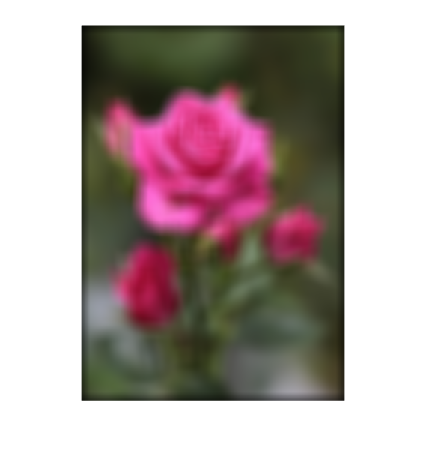

imshow(Iavg,[])

**Comments**: As W increases in the code, the image becomes blurrier and the corners experience a greater sharp shadow effect due to convolution at the edges.

**Task 2**

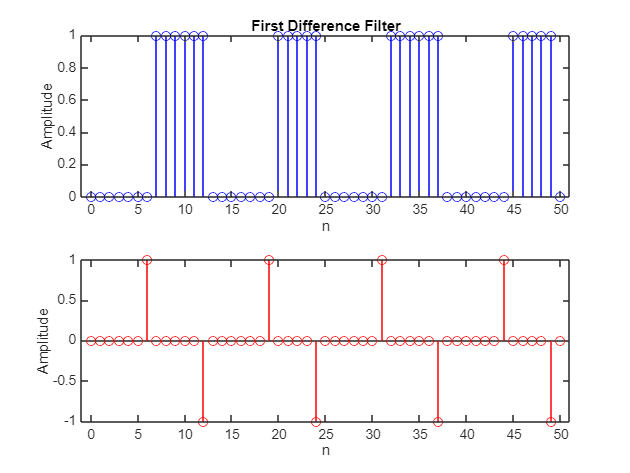

clear all
clc
close all
n = 0:50;
x = double((sin(0.5*n)+0.2) < 0);
h = [1 -1];
y = conv(x, h, "same");
figure;
subplot 211;
stem(n, x, 'b');
xlabel('n');
ylabel('Amplitude');
title('First Difference Filter');
subplot 212;
stem(n, y, 'r');
xlabel('n');
ylabel('Amplitude');

**Comments:** The first difference filter calculates the difference between successive values in a signal to identify transitions. When applied to x[n], it draws attention to changes, which makes it helpful for edge detection. We can observe how the filter improves transitions—a crucial idea in image processing and barcode detection—by charting both signals.

**Task 3**

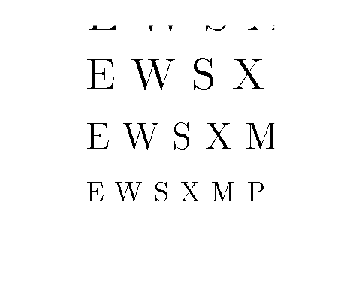

clear all
clc
close all
load('echart.mat')
imshow(echart)

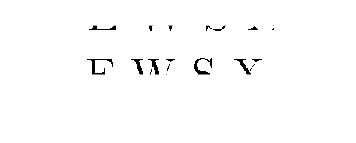

imshow(echart(1:65,:))

x = echart(65,:)

x =    255   255   255   255   255   255   255   255   255   255   255   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255


h = [1 -1];
y = conv(h, x)

y =    255     0     0     0     0     0     0     0     0     0     0     0     0  -255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


**Comments**: The white pixels in the row are represented by the 0 (zeros), and the black pixels are represented by the 255 (ones). A color that falls between the two extremes of black and white will be represented by any non-zero value in the output signal.

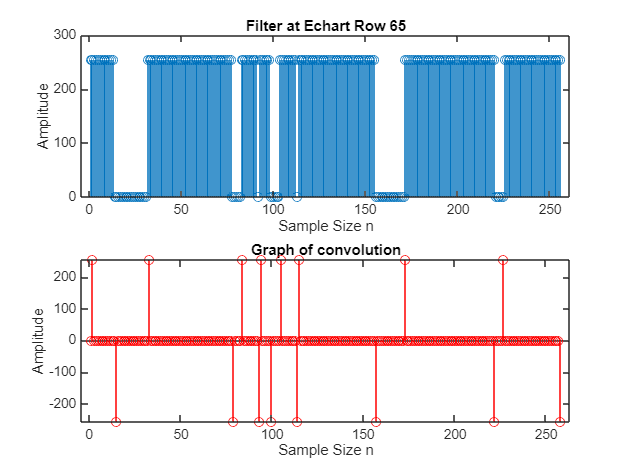

figure;
subplot 211;
stem(x);
title('Filter at Echart Row 65')
xlabel('Sample Size n')
ylabel('Amplitude')
subplot 212;
stem([0 y],'r');
title('Graph of convolution')
xlabel('Sample Size n')
ylabel('Amplitude')

**Task 4**

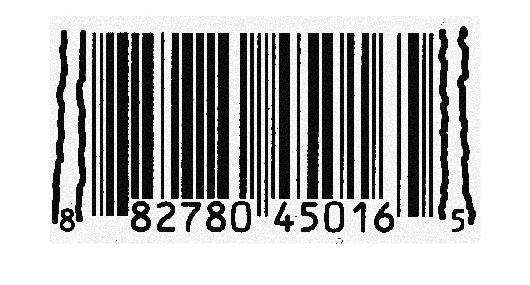

clear all;
clc;
close all;

% Step 1: Read and Display the Barcode Image
bar = imread("HP110v3.png"); % Read the barcode image
imshow(bar); % Display the barcode image


% Extract one row from the middle of the image to define a 1D signal
siz = size(bar)/2;
xn = bar(siz(1)/2,:); % Extract a row from the middle of the image

% Step 2: Apply First Difference Filter
hn = [1 -1]; % Define the first difference filter
yn = conv(xn, hn); % Convolve the row signal with the first difference filter

% Display variable information
whos bar % Shows details of the "bar" variable

  Name        Size              Bytes  Class    Attributes

  bar       500x948            474000  uint8              



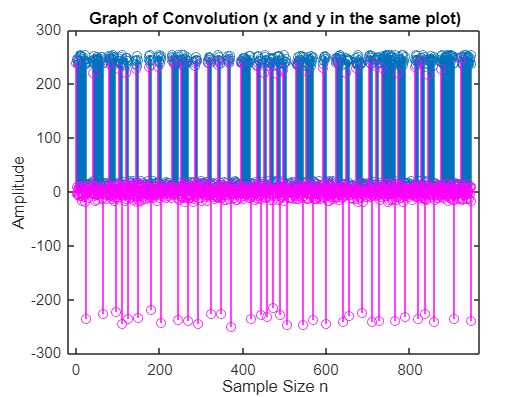


figure;
stem(xn); % Plot the original barcode row signal
hold on;
stem(yn, 'm'); % Plot the convolved signal in magenta
hold off;
title('Graph of Convolution (x and y in the same plot)');
xlabel('Sample Size n');
ylabel('Amplitude');

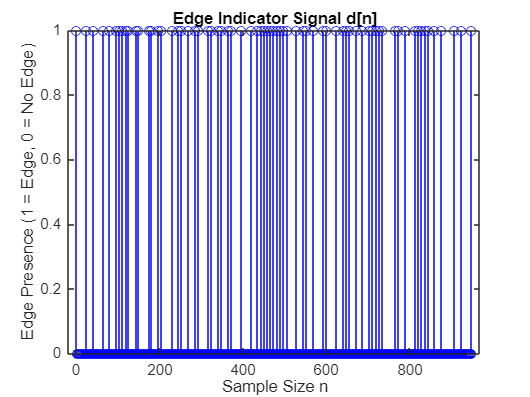


% Step 3: Define Threshold and Detect Edges
% Set threshold tau based on 84% of the peak magnitude in yn
tau = round(max(abs(yn)) * 0.84); 

% Indicator function to mark edges where magnitude exceeds the threshold
dn = abs(yn) >= tau; 

% Plot the Edge Indicator Signal
figure;
stem(dn, 'b'); % Plot the detected edges
title('Edge Indicator Signal d[n]');
xlabel('Sample Size n');
ylabel('Edge Presence (1 = Edge, 0 = No Edge)');


% Step 4: Find Edge Indices
ln = find(dn) % Get indices of detected edges

ln =      1    25    41    65    80    95   104   111   119   126   143   149   175   181   198   205   230   246   253   269   285   292   316   324   340   347   364   371   395   419   435   443   451   458   466   474   482   490   498   506   529   545   553   569   593   600   624   640   648   656



% Step 5: Apply First Difference Filter to Edge Indices
deltan = conv(ln, hn) % Compute the width differences

deltan =      1    24    16    24    15    15     9     7     8     7    17     6    26     6    17     7    25    16     7    16    16     7    24     8    16     7    17     7    24    24    16     8     8     7     8     8     8     8     8     8    23    16     8    16    24     7    24    16     8     8



% Step 6: Compute the Basic Width Theta
% Given that the total width is 95 units and there are 59 bars
theta = (59 * 12) / 95

theta = 7.4526


% Step 7: Normalize and Round the Differences
fixed_deltan = round((deltan(7:65)) ./ theta) % Normalize widths to nearest integer values

fixed_deltan =      1     1     1     1     2     1     3     1     2     1     3     2     1     2     2     1     3     1     2     1     2     1     3     3     2     1     1     1     1     1     1     1     1     1     3     2     1     2     3     1     3     2     1     1     2     2     2     1     1     1



% Step 8: Decode the UPC Barcode
decodeUPC(fixed_deltan) % Call the provided function to decode the barcode

ssbeg =      1     1     1


ans =      8     8     2     7     8     0     4     5     0     1     6     5
